#  definition of variables

clc;
clear;

m=1; %mass
l=1; %length
g=9.81; %gravity
J=m*l*l/3; %moment of inertia for rod with axis passing through one end
R=1.22;
L=5.13;
Km=0.363;
Kt=0.31;
n=50;
max_time=40;

global time_prior integral error_prior;
time_prior = 0; 
integral=0;
error_prior=0;

## ode45 and plotting

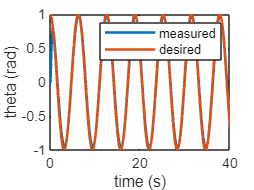

tspan=[0 max_time];
x_init=transpose([0 0 0 1]); %initial value of state space
[t, x]=ode45(@(t, x) odefcn(t, x), tspan, x_init);
y1 = x(:, 1);
y2= x(:, 4);
graph=plot(t, y1, t, y2);
legend('measured', 'desired')
xlabel('time (s)');
ylabel('theta (rad)');
set(graph, 'linewidth', 1.5);

## function definitions

function dxdt = odefcn(t, x)
    m=1; %mass
    l=1; %length
    g=9.81; %gravity
    J=m*l*l/3; %moment of inertia for rod with axis passing through one end
    R=1.22;
    L=5.13;
    Km=0.363;
    Kt=0.31;
    n=50;
    global time_prior error_prior;

    %the following is our state space definition
    tht=x(1, 1); %theta_actual
    tht_dot=x(2, 1); %derivative of theta
    i=x(3, 1); %current
    trajectory=x(4, 1);
    
    theta_desired=cos(t);
    error=theta_desired-tht;
    %error_dot=-tht_dot; %old method, doesn't work for trajectory tracking
    error_dot=(error-error_prior);
    V=control(t, error, time_prior, error_dot); %voltage
    %clipping of voltage
    V=clip(V, 10, -10);
    
    error_prior=error;
    time_prior=t;
    
    %differential equations for ode45
    dxdt=zeros(4, 1);
    dxdt(1, 1)=tht_dot;
    dxdt(2, 1)=(n*Kt/J)*(i-(m*g*l*cos(tht))/(2*n*Kt));
    dxdt(3, 1)=(V-(R*i)-(Km*n*tht_dot)/L);
    dxdt(4, 1)=-sin(t); %calculate this derivative by using diff in command window
end

function u = control(t, error, time_prior, error_dot)
    %PID gains
    kp=40; %21
    ki=5; %10
    kd=60; %60
    bias=0; %0.32 for theta_desired=0.5
    
    global integral;
    integral=integral+ki*error*(t-time_prior);
    u=kp*error+integral+kd*error_dot*1000+bias;
end

function val = clip(val, upper_bound, lower_bound)
   if val>upper_bound
        val=upper_bound;
    end
    if val<lower_bound
        val=lower_bound;
    end 
end
